# AER 715 Introduction to Avionics and Systems

Lab 5 - Control System Testing and Analysis

Bryan Kikuta - 501039179

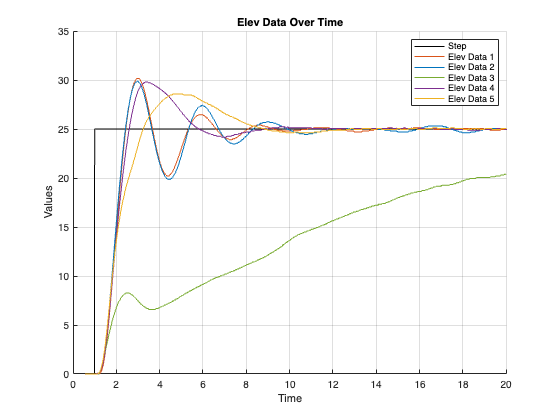

% Num | Travel  | Elevation
% 1   | Base    | Base
% 2   | G2_trav | Base
% 3   | G2_trav | G2_elev1
% 4   | G2_trav | G2_elev2
% 5   | G2_trav | G2_elev3

% Load trial 1 data
data_1 = load('1.mat');
time_elev_1 = data_1.elevData1.time;
values_elev_1 = data_1.elevData1.signals.values;
time_trav_1 = data_1.travData1.time;
values_trav_1 = data_1.travData1.signals.values;

% Load trial 2 data
data_2 = load('2.mat');
time_elev_2 = data_2.elevData1.time;
values_elev_2 = data_2.elevData1.signals.values;
time_trav_2 = data_2.travData1.time;
values_trav_2 = data_2.travData1.signals.values;

% Load trial 3 data
data_3 = load('3.mat');
time_elev_3 = data_3.elevData1.time;
values_elev_3 = data_3.elevData1.signals.values;
time_trav_3 = data_3.travData1.time;
values_trav_3 = data_3.travData1.signals.values;

% Load trial 4 data
data_4 = load('4.mat');
time_elev_4 = data_4.elevData1.time;
values_elev_4 = data_4.elevData1.signals.values;
time_trav_4 = data_4.travData1.time;
values_trav_4 = data_4.travData1.signals.values;

% Load trial 5 data
data_5 = load('5.mat');
time_elev_5 = data_5.elevData1.time;
values_elev_5 = data_5.elevData1.signals.values;
time_trav_5 = data_5.travData1.time;
values_trav_5 = data_5.travData1.signals.values;

% Plot the data
figure_elev = figure;
hold on;
plot(time_elev_1(1:1946,:), values_elev_1(1:1946,1), '-', 'Color', [0, 0, 0], 'DisplayName', 'Step');
plot(time_elev_1(1:1946,:), values_elev_1(1:1946,2), '-', 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Elev Data 1');
plot(time_elev_2(1:1946,:), values_elev_2(1:1946,2), '-', 'Color', [0, 0.45, 0.74], 'DisplayName', 'Elev Data 2');
plot(time_elev_3(1:1946,:), values_elev_3(1:1946,2), '-', 'Color', [0.47, 0.67, 0.19], 'DisplayName', 'Elev Data 3');
plot(time_elev_4(1:1946,:), values_elev_4(1:1946,2), '-', 'Color', [0.49, 0.18, 0.56], 'DisplayName', 'Elev Data 4');
plot(time_elev_5(1:1946,:), values_elev_5(1:1946,2), '-', 'Color', [0.93, 0.69, 0.13], 'DisplayName', 'Elev Data 5');
xlabel('Time');
ylabel('Values');
legend;
grid on;
title('Elev Data Over Time');

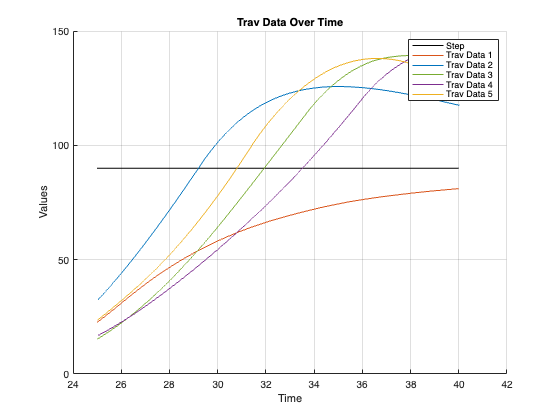

figure_trav = figure;
hold on;
plot(time_trav_1(2446:3946,:), values_trav_1(2446:3946,1), '-', 'Color', [0, 0, 0], 'DisplayName', 'Step');
plot(time_trav_1(2446:3946,:), values_trav_1(2446:3946,2), '-', 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Trav Data 1');
plot(time_trav_2(2446:3946,:), values_trav_2(2446:3946,2), '-', 'Color', [0, 0.45, 0.74], 'DisplayName', 'Trav Data 2');
plot(time_trav_3(2446:3946,:), values_trav_3(2446:3946,2), '-', 'Color', [0.47, 0.67, 0.19], 'DisplayName', 'Trav Data 3');
plot(time_trav_4(2446:3946,:), values_trav_4(2446:3946,2), '-', 'Color', [0.49, 0.18, 0.56], 'DisplayName', 'Trav Data 4');
plot(time_trav_5(2446:3946,:), values_trav_5(2446:3946,2), '-', 'Color', [0.93, 0.69, 0.13], 'DisplayName', 'Trav Data 5');
xlabel('Time');
ylabel('Values');
legend;
grid on;
title('Trav Data Over Time');